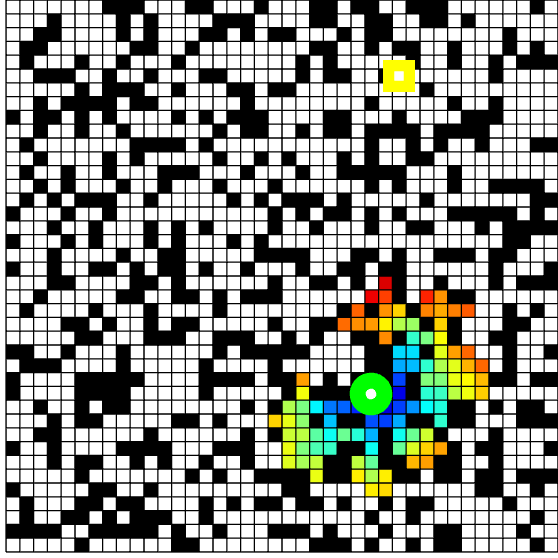

%matlab初始化

clc;             %清除命令窗口的内容
clear all;       %清除工作空间的所有变量，函数，和MEX文件
close all;       %关闭所有的figure窗口

%方格数及障碍物比例的设定
n = 40;   % 产生一个n x n的方格，修改此值可以修改生成图片的方格数
wallpercent = 0.4;  % 这个变量代表生成的障碍物占总方格数的比例 ，如0.5 表示障碍物占总格数的50%

%方格以及障碍物的创建
[field, startposind, goalposind, costchart, fieldpointers] =initializeField(n,wallpercent); %随机生成包含障碍物，起始点，终止点等信息的矩阵

% 路径规划中用到的一些矩阵的初始化
setOpen = [startposind]; setOpenCosts = [0]; setOpenHeuristics = [Inf];
setClosed = []; setClosedCosts = [];
movementdirections = {'R','L','D','U'};  %移动方向


% 这个函数用来随机生成环境，障碍物，起点，终点
axishandle = createFigure(field,costchart,startposind,goalposind);    %将随机生成的方格及障碍物的数据生成图像

%%

% 这个while循环是本程序的核心，利用循环进行迭代来寻找终止点
% ismember 判断数组元素是否为集数组成员
while ~max(ismember(setOpen,goalposind)) && ~isempty(setOpen)
    [temp, ii] = min(setOpenCosts + setOpenHeuristics);     %寻找拓展出来的最小值 
    %[temp, ii] = min(setOpenCosts + setOpenHeuristics) 
    % 函数的返回值ii是（setOpenCosts + setOpenHeuristics）中的最小值在矩阵中的行数 ，
    % 返回值 temp是 （setOpen Costs + setOpenHeuristics） 中最小值

    %这个函数的作用就是把输入的点作为父节点，然后进行拓展找到子节点，并且找到子节点的代价，并且把子节点距离终点的代价找到
    [costs,heuristics,posinds] = findFValue(setOpen(ii),setOpenCosts(ii), field,goalposind,'euclidean');
 
  setClosed = [setClosed; setOpen(ii)];     % 将找出来的拓展出来的点中代价最小的那个点串到矩阵setClosed 中 
  setClosedCosts = [setClosedCosts; setOpenCosts(ii)];    % 将拓展出来的点中代价最小的那个点的代价串到矩阵setClosedCosts 中
  
  % 从setOpen中删除刚才放到矩阵setClosed中的那个点
  %如果这个点位于矩阵的内部
  if (ii > 1 && ii < length(setOpen))
    setOpen = [setOpen(1:ii-1); setOpen(ii+1:end)];
    setOpenCosts = [setOpenCosts(1:ii-1); setOpenCosts(ii+1:end)];
    setOpenHeuristics = [setOpenHeuristics(1:ii-1); setOpenHeuristics(ii+1:end)];
    
  %如果这个点位于矩阵第一行
  elseif (ii == 1)
    setOpen = setOpen(2:end);
    setOpenCosts = setOpenCosts(2:end);
    setOpenHeuristics = setOpenHeuristics(2:end);
    
  %如果这个点位于矩阵的最后一行
  else
    setOpen = setOpen(1:end-1);
    setOpenCosts = setOpenCosts(1:end-1);
    setOpenHeuristics = setOpenHeuristics(1:end-1);
  end
  
 %%  
  % 把拓展出来的点中符合要求的点放到setOpen 矩阵中，作为待选点
  for jj=1:length(posinds)
  
    if ~isinf(costs(jj))   % 判断该点（方格）处没有障碍物
        
      % 判断一下该点是否 已经存在于setOpen 矩阵或者setClosed 矩阵中
      % 如果我们要处理的拓展点既不在setOpen 矩阵，也不在setClosed 矩阵中
      if ~max([setClosed; setOpen] == posinds(jj))
        fieldpointers(posinds(jj)) = movementdirections(jj);
        costchart(posinds(jj)) = costs(jj);
        setOpen = [setOpen; posinds(jj)];
        setOpenCosts = [setOpenCosts; costs(jj)];
        setOpenHeuristics = [setOpenHeuristics; heuristics(jj)];
        
      % 如果我们要处理的拓展点已经在setOpen 矩阵中
      elseif max(setOpen == posinds(jj))
        I = find(setOpen == posinds(jj));
        % 如果通过目前的方法找到的这个点，比之前的方法好（代价小）就更新这个点
        if setOpenCosts(I) > costs(jj)
          costchart(setOpen(I)) = costs(jj);
          setOpenCosts(I) = costs(jj);
          setOpenHeuristics(I) = heuristics(jj);
          fieldpointers(setOpen(I)) = movementdirections(jj);
        end
        
        % 如果我们要处理的拓展点已经在setClosed 矩阵中
      else
        I = find(setClosed == posinds(jj));
        % 如果通过目前的方法找到的这个点，比之前的方法好（代价小）就更新这个点
        if setClosedCosts(I) > costs(jj)
          costchart(setClosed(I)) = costs(jj);
          setClosedCosts(I) = costs(jj);
          fieldpointers(setClosed(I)) = movementdirections(jj);
        end
      end
    end
  end
  
 %% 
  
  if isempty(setOpen) break; end
  set(axishandle,'CData',[costchart costchart(:,end); costchart(end,:) costchart(end,end)]);
  set(gca,'CLim',[0 1.1*max(costchart(find(costchart < Inf)))]);
  drawnow; 
end


%%

%调用findWayBack函数进行路径回溯，并绘制出路径曲线
if max(ismember(setOpen,goalposind))
  disp('Solution found!');
  p = findWayBack(goalposind,fieldpointers); % 调用findWayBack函数进行路径回溯，将回溯结果放于矩阵P中
  plot(p(:,2)+0.5,p(:,1)+0.5,'Color',0.2*ones(3,1),'LineWidth',4);  %用 plot函数绘制路径曲线
  drawnow;
  drawnow;
 
end

%% 

%findWayBack函数用来进行路径回溯，这个函数的输入参数是终止点goalposind和矩阵fieldpointers，输出参数是P

function p = findWayBack(goalposind,fieldpointers)

    n = length(fieldpointers);  % 获取环境的长度也就是n
    posind = goalposind;
    [py,px] = ind2sub([n,n],posind); % 将索引值posind转换为坐标值 [py,px]
    p = [py px];
    
    %利用while循环进行回溯，当我们回溯到起始点的时候停止，也就是在矩阵fieldpointers中找到S时停止
    while ~strcmp(fieldpointers{posind},'S')
      switch fieldpointers{posind}
          
        case 'L' % ’L’ 表示当前的点是由左边的点拓展出来的
          px = px - 1;
        case 'R' % ’R’ 表示当前的点是由右边的点拓展出来的
          px = px + 1;
        case 'U' % ’U’ 表示当前的点是由上面的点拓展出来的
          py = py - 1;
        case 'D' % ’D’ 表示当前的点是由下边的点拓展出来的
          py = py + 1;
      end
      p = [p; py px];
      posind = sub2ind([n n],py,px);% 将坐标值转换为索引值
    end
end

%% 
%这个函数的作用就是把输入的点作为父节点，然后进行拓展找到子节点，并且找到子节点的代价，并且把子节点距离终点的代价找到。
%函数的输出量中costs表示拓展的子节点到起始点的代价，heuristics表示拓展出来的点到终止点的距离大约是多少，posinds表示拓展出来的子节点
function [cost,heuristic,posinds] = findFValue(posind,costsofar,field,goalind,heuristicmethod)
    n = length(field);  % 获取矩阵的长度
    [currentpos(1) currentpos(2)] = ind2sub([n n],posind);   %将要进行拓展的点（也就是父节点）的索引值拓展成坐标值
    [goalpos(1) goalpos(2)] = ind2sub([n n],goalind);        %将终止点的索引值拓展成坐标值
    cost = Inf*ones(4,1); heuristic = Inf*ones(4,1); pos = ones(4,2); %将矩阵cost和heuristic初始化为4x1的无穷大值的矩阵，pos初始化为4x2的值为1的矩阵
    
    % 拓展方向一
    newx = currentpos(2) - 1; newy = currentpos(1);
    if newx > 0
      pos(1,:) = [newy newx];
      switch lower(heuristicmethod)
        case 'euclidean'
          heuristic(1) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
        case 'taxicab'
          heuristic(1) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
      end
      cost(1) = costsofar + field(newy,newx);
    end

    % 拓展方向二
    newx = currentpos(2) + 1; newy = currentpos(1);
    if newx <= n
      pos(2,:) = [newy newx];
      switch lower(heuristicmethod)
        case 'euclidean'
          heuristic(2) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
        case 'taxicab'
          heuristic(2) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
      end
      cost(2) = costsofar + field(newy,newx);
    end

    % 拓展方向三
    newx = currentpos(2); newy = currentpos(1)-1;
    if newy > 0
      pos(3,:) = [newy newx];
      switch lower(heuristicmethod)
        case 'euclidean'
          heuristic(3) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
        case 'taxicab'
          heuristic(3) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
      end
      cost(3) = costsofar + field(newy,newx);
    end

    % 拓展方向四
    newx = currentpos(2); newy = currentpos(1)+1;
    if newy <= n
      pos(4,:) = [newy newx];
      switch lower(heuristicmethod)
        case 'euclidean'
          heuristic(4) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
        case 'taxicab'
          heuristic(4) = abs(goalpos(2)-newx) + abs(goalpos(1)-newy);
      end
      cost(4) = costsofar + field(newy,newx);
    end
     posinds = sub2ind([n n],pos(:,1),pos(:,2)); % 将拓展出来的子节点的坐标值转换为索引值
end

%% 
%这个矩阵的作用就是随机生成环境，障碍物，起始点，终止点等
function [field, startposind, goalposind, costchart, fieldpointers] = initializeField(n,wallpercent)
    field = ones(n,n) + 10*rand(n,n);%生成一个n*n的单位矩阵+0到10范围内的一个随机数
    field(ind2sub([n n],ceil(n^2.*rand(n*n*wallpercent,1)))) = Inf;%向上取整
    % 随机生成起始点和终止点
    startposind = sub2ind([n,n],ceil(n.*rand),ceil(n.*rand));  %随机生成起始点的索引值
    goalposind = sub2ind([n,n],ceil(n.*rand),ceil(n.*rand));   %随机生成终止点的索引值
    field(startposind) = 0; field(goalposind) = 0;  %把矩阵中起始点和终止点处的值设为0
    
    costchart = NaN*ones(n,n);%生成一个nxn的矩阵costchart，每个元素都设为NaN。就是矩阵初始NaN无效数据
    costchart(startposind) = 0;%在矩阵costchart中将起始点位置处的值设为0
    
    % 生成元胞数组
    fieldpointers = cell(n,n);%生成元胞数组n*n
    fieldpointers{startposind} = 'S'; fieldpointers{goalposind} = 'G'; %将元胞数组的起始点的位置处设为 'S'，终止点处设为'G'
    fieldpointers(field==inf)={0};
    
   
end
% end of this function

%%
%利用随机生成的环境数据来进行环境的绘制
function axishandle = createFigure(field,costchart,startposind,goalposind)

      % 这个if..else结构的作用是判断如果没有打开的figure图，则按照相关设置创建一个figure图
      if isempty(gcbf)                                       %gcbf是当前返回图像的句柄，isempty(gcbf)假如gcbf为空的话，返回的值是1，假如gcbf为非空的话，返回的值是0
      figure('Position',[460 65 700 700], 'MenuBar','none');  %对创建的figure图像进行设置，设置其距离屏幕左侧的距离为450，距离屏幕下方的距离为50，长度和宽度都为700，并且关闭图像的菜单栏
      axes('position', [0.01 0.01 0.99 0.99]);               %设置坐标轴的位置，左下角的坐标设为0.01,0.01   右上角的坐标设为0.99 0.99  （可以认为figure图的左下角坐标为0 0   ，右上角坐标为1 1 ）
      else
      gcf; cla;   %gcf 返回当前 Figure 对象的句柄值，然后利用cla语句来清除它
      end
      
      n = length(field);  %获取矩阵的长度，并赋值给变量n
      field(field < Inf) = 0; %将fieid矩阵中的随机数（也就是没有障碍物的位置处）设为0
      pcolor(1:n+1,1:n+1,[field field(:,end); field(end,:) field(end,end)]);%多加了一个重复的（由n X n变为 n+1 X n+1 ）
 
      cmap = flipud(colormap('jet'));  %生成的cmap是一个256X3的矩阵，每一行的3个值都为0-1之间数，分别代表颜色组成的rgb值
      cmap(1,:) = zeros(3,1); cmap(end,:) = ones(3,1); %将矩阵cmap的第一行设为0 ，最后一行设为1
      colormap(flipud(cmap)); %进行颜色的倒转 
      hold on;
      axishandle = pcolor([1:n+1],[1:n+1],[costchart costchart(:,end); costchart(end,:) costchart(end,end)]);  %将矩阵costchart进行拓展，插值着色后赋给axishandle
      [goalposy,goalposx] = ind2sub([n,n],goalposind);
      [startposy,startposx] = ind2sub([n,n],startposind);
       plot(goalposx+0.5,goalposy+0.5,'ys','MarkerSize',10,'LineWidth',6);
       plot(startposx+0.5,startposy+0.5,'go','MarkerSize',10,'LineWidth',6);
       %uicontrol('Style','pushbutton','String','RE-DO', 'FontSize',12, 'Position', [1 1 60 40], 'Callback','astardemo');
end
